Amp and phaze as a function of R

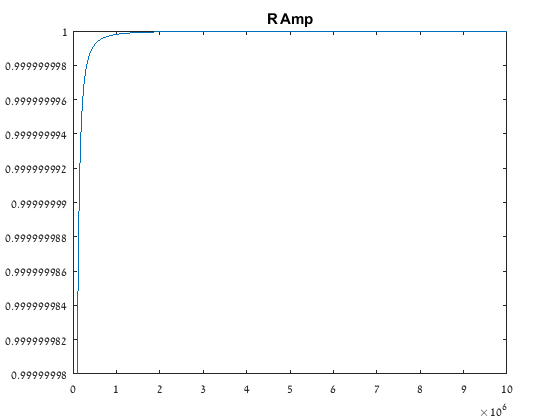

W=5000;
Start = 10^5;
End = 10^7;
Num_Points = 1000;
R=linspace(Start,End,Num_Points);
C=10^-5;
A=(R.*C*W)./((1+(W^2*C^2.*R.^2)).^0.5);
Phi=atan(1./W*C.*R);
plot(R,A);
title('R Amp');

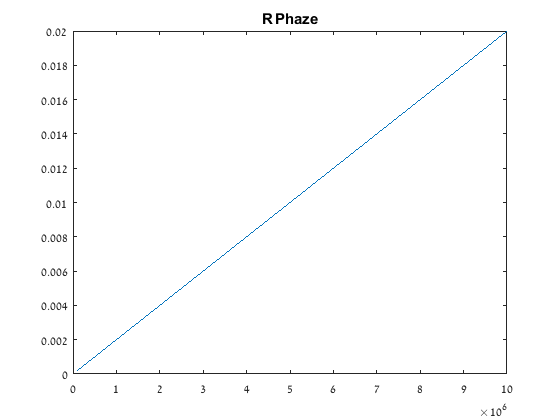

plot(R,Phi);
title('R Phaze');

Amp and phaze as a function of C

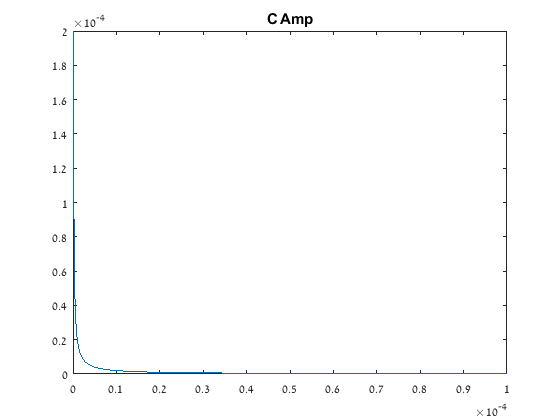

W=5000;
Start = 10^-4;
End = 10^-7;
Num_Points = 1000;
C=linspace(Start,End,Num_Points);
R=10^7;
A=1./(1+(W^2*R^2.*C.^2)).^0.5;
Phi=atan(W*R.*C);
plot(C,A);
title('C Amp');

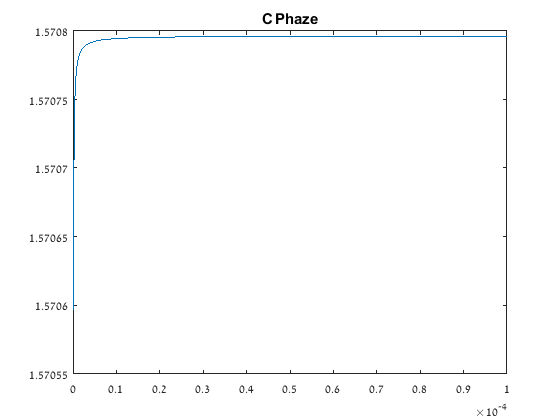

plot(C,Phi);
title('C Phaze');

Real data of V_out as a function of R

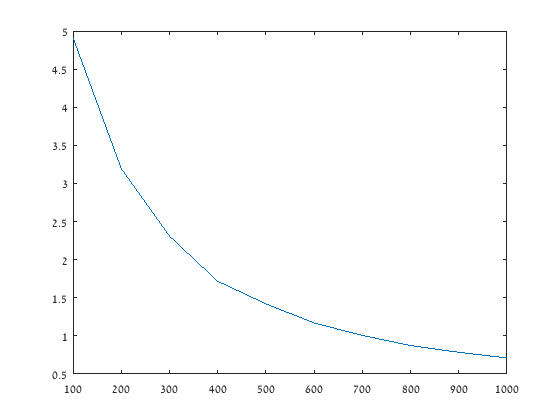

R=470000; C=4*10^-9;
W_in=[100,200,300,400,500,600,700,800,900,1000];
V_out=[6.64,4.32,3.12,2.32,1.92,1.58,1.36,1.18,1.06,0.96];
normal=4.914/V_out(1); %the value with no extra resistence.
V_out=V_out.*normal;
plot(W_in,V_out);

diffrent version

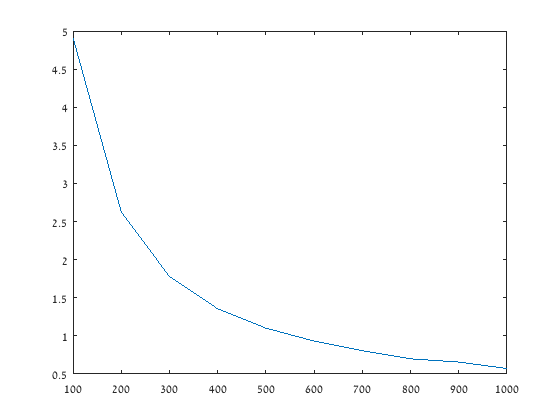

R=470000; C=8*10^-9;
W_in=[100,200,300,400,500,600,700,800,900,1000];
V_out=[4.64,2.48,1.68,1.28,1.04,0.88,0.76,0.66,0.62,0.54];
normal=4.68/V_out(1); %the value with no extra resistence.
V_out=V_out.*normal;
plot(W_in,V_out);